#  DC Motor Dynamics

[https://www3.diism.unisi.it/~control/ctm/examples/motor/digital.html](https://www3.diism.unisi.it/~control/ctm/examples/motor/digital.html)

[https://www3.diism.unisi.it/~control/ctm/examples/motor/PID2.html](https://www3.diism.unisi.it/~control/ctm/examples/motor/PID2.html)

[https://link.springer.com/chapter/10.1007/978-981-33-4080-0_18](https://link.springer.com/chapter/10.1007/978-981-33-4080-0_18) 

[https://iopscience.iop.org/article/10.1088/1757-899X/190/1/012001/pdf](https://iopscience.iop.org/article/10.1088/1757-899X/190/1/012001/pdf)  

[https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9324733/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9324733/) 

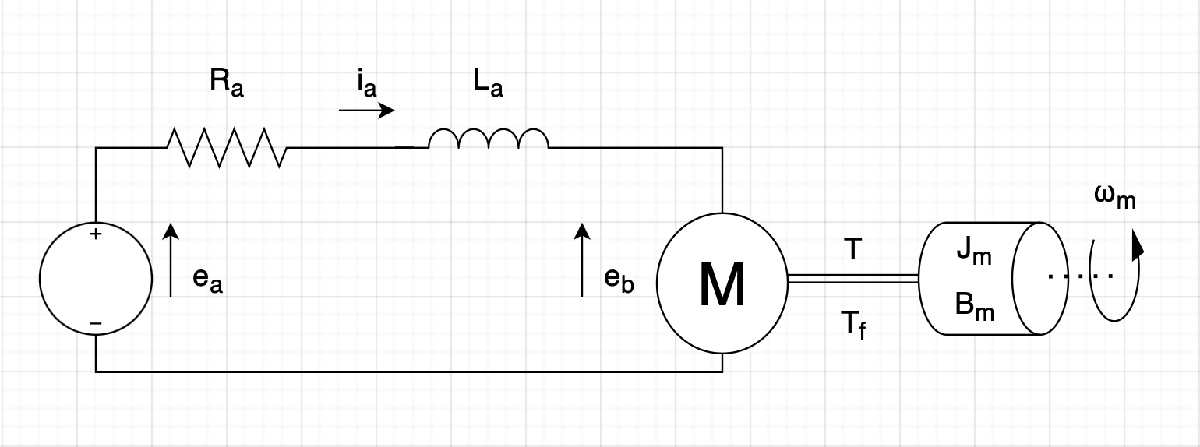

$e_a \left(t\right)$     Armature terminal voltage    [V]

$e_b \left(t\right)$     Back emf                              [V]

$T_m \left(t\right)$     Motor Torque                       [Nm]

$T_f \left(t\right)$     Static Friction Torque           [Nm]

$\omega_m \left(t\right)$     Motor Speed                       [rad/s]

clf
clc
Jm = 0.01;  % rotational inertia           [Nms^2/rad]
Bm = 0.0;   % vicous friction              [Nms/rad]
kt = 0.06;  % Motor Torque constant        []
ke = 0.06;  % Motor Back EMF constant      []
Ra = 4;     % armature resistance          [Ω]
La = 0.5;   % armature inductance          [H]

## CT Electromechanical System of Equations


$$e_a \left(t\right)=R_a i_a \left(t\right)+L_a \;\frac{\mathrm{d}}{\mathrm{d}t}i_a \left(t\right)+e_b \left(t\right)\;$$



$$e_b \left(t\right)=K_e \omega_m \left(t\right)$$



$$T_m \left(t\right)=K_t i_a \left(t\right)\;$$



$$T_m \left(t\right)=J_m \;\frac{\mathrm{d}}{\mathrm{d}t}\omega_m \left(t\right)+B_m \omega_m \left(t\right)$$
 

## S Domain System of Equations


$$E_b \left(s\right)=K_e \Omega_m \left(s\right)$$



$$T_m \left(s\right)=K_t I_a \left(s\right)=\left(sJ_m +B_m \right)\Omega_m \left(s\right)\;$$



$$I_a \left(s\right)=\frac{1}{sL_a +R_a }\;\left\lbrack E_a \left(s\right)-E_b \left(s\right)\right\rbrack$$


Input and Output Equations


$$E_a \left(s\right)=R_a I_a \left(s\right)+{\textrm{sL}}_a \;I_a \left(s\right)+E_b \left(s\right)\;$$



$$\Omega_m \left(s\right)=T_m \left(s\right)\frac{1}{sJ_m +B_m }$$


## DC Motor Transfer Function

## 
$$G\left(s\right)=\;\frac{\Omega_m \left(s\right)}{E_a \left(s\right)}=\frac{K_t }{s^2 \left(L_a J_m \right)+s\left(R_a J_m +B_m L_a \right)+\left(K_t K_e +R_a B_m \right)}$$


% DC Motor Transfer Function
numS = kt;
denS = [La*Jm , (Ra*Jm + Bm*La),(kt*ke + Ra*Bm)];
motor_tf = tf(numS, denS);
% DC Motor StateSpace Model
motor_ss = ss(motor_tf);
ctrb_mat = ctrb(motor_ss)

ctrb_mat =      4   -32
     0     4


%rank(ctrb_mat) % full state plant means its controlable

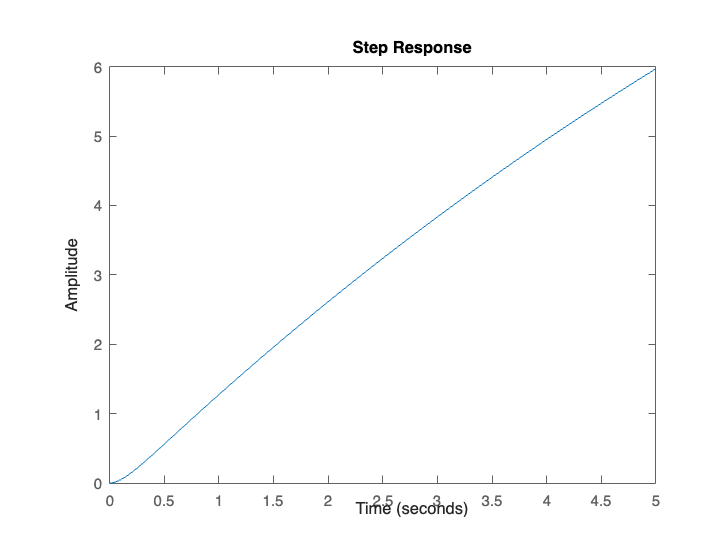

% Simulate the Open Loop response of the system
t=0:0.01:5; % time series (s)
step(motor_tf, t);

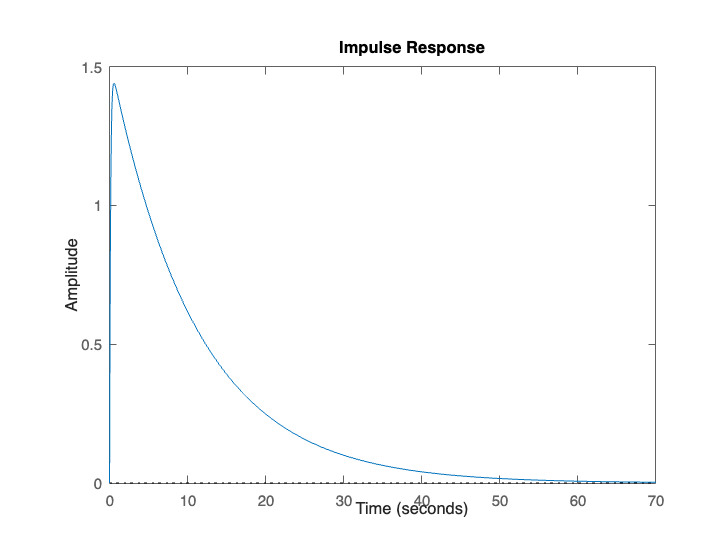

impulse(motor_tf);

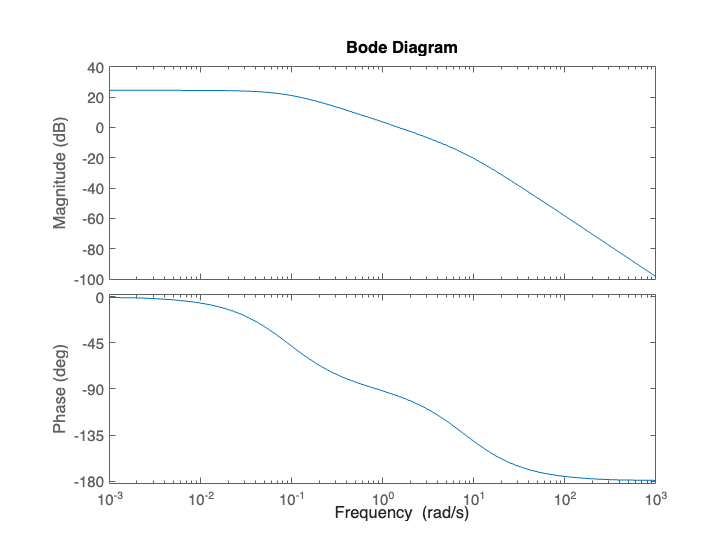

bode(motor_tf);

## DC Motor Model Z Domain

Desing Requierements:

SettelingTime: < 2 s

Overshoot: < 5%

SteadyState Error: < 1%

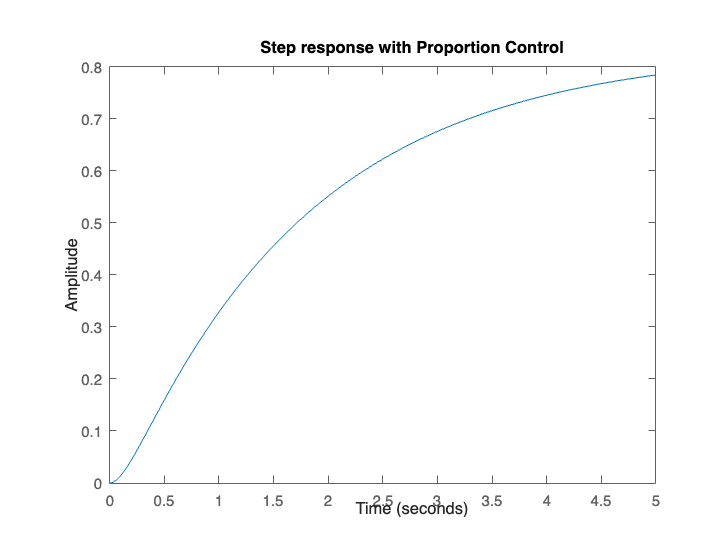

Kp = 0.3;
Ki = 0.9;
Kd = 0;

vMin = -12;
vMax = 12;
% Proportional Control
numA = Kp*numS;
denA = denS;
[numAC,denAC]=cloop(numA,denA);
step(numAC,denAC,t)
title('Step response with Proportion Control')

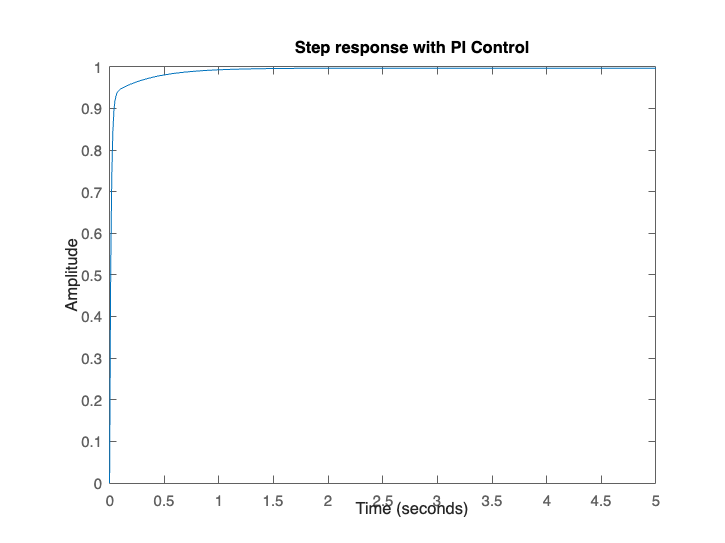


% Discreet PID controler
numc=[Kp, Ki, Kd];
denc=[1 0];
numa=conv(numS * gR,numc);
dena=conv(denS,denc);
[numac,denac]=cloop(numa,dena);
step(numac,denac, t)
title('Step response with PI Control')